# **Robot Model**

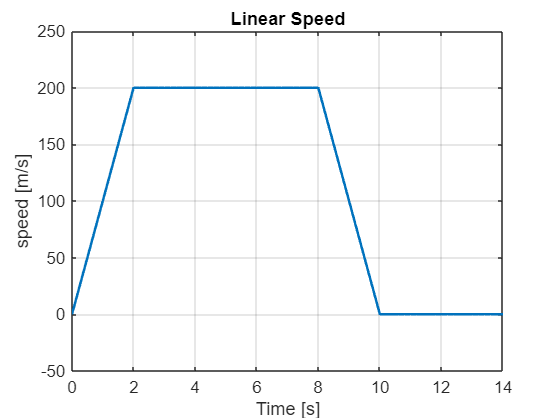

clear;
clc;
Ts = 0.2;
% Distance to Point P
l = 1;

% Delta Time
delta_t = Ts;
% Time
t = 0:delta_t:10+20*Ts;

% Trapezoidal Speed
speed_max = 200;
v = speed_max/2*ramp(t) - speed_max/2*ramp(t-2) - speed_max/2*ramp(t-8) + speed_max/2*ramp(t-10);

% Speed Plot
figure;
plot(t, v, 'LineWidth', 1.5);
grid on;
xlabel('Time [s]');
ylabel('speed [m/s]');
title('Linear Speed');

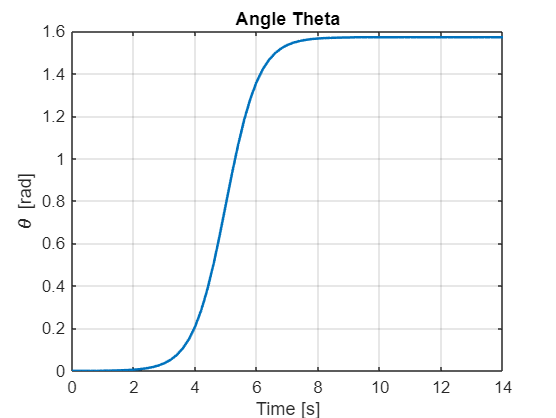

% Parameters
theta_0 = 0;          % [rad]
theta_f = pi/2;         % [rad]
t_start_turn = 1;          % Turn start [s]
t_end_turn = 9;             % Turn end [s]
k = 15;                     % sigmoid slope

% Angle
theta_ref = zeros(size(t));

for i = 1:length(t)
    if t(i) < t_start_turn
        % Before starting the turn, we keep the same heading
        theta_ref(i) = theta_0;
    elseif t(i) > t_end_turn
        % After the end of the turn, we keep the same heading
        theta_ref(i) = theta_f;
    else
        % in the turn we use a sigmoid
        tau = (t(i) - t_start_turn) / (t_end_turn - t_start_turn);  % time normalization
        theta_ref(i) = theta_0 + (theta_f - theta_0) / (1 + exp(-k * (tau - 0.5)));
    end
end

% Plot of the heading angle
figure;
plot(t, theta_ref, 'LineWidth', 1.5);
grid on;
xlabel('Time [s]');
ylabel('\theta [rad]');
title('Angle Theta');

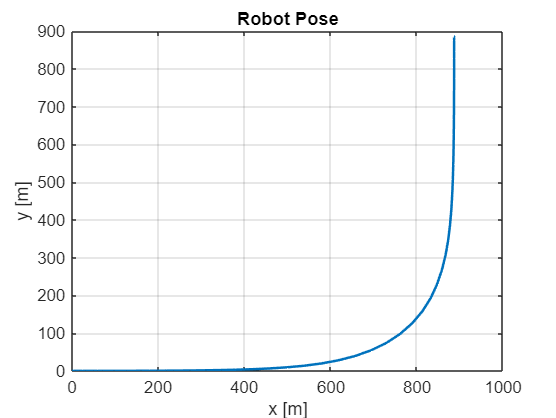

% Initial Position
x0 = 0;
y0 = 0;

% Trajectory of the Robot
pose = zeros(2, length(t));
pose(:,1) = [x0 y0]';

for i = 2:length(t)
    % Update x
    pose(1, i) = pose(1, i-1) + v(i)*cos(theta_ref(i))*delta_t;
    % Upate y
    pose(2, i) = pose(2, i-1) + v(i)*sin(theta_ref(i))*delta_t;
end

figure()
plot(pose(1,:), pose(2,:), 'LineWidth', 1.5);
grid on;
xlabel('x [m]');
ylabel('y [m]');
title('Robot Pose');

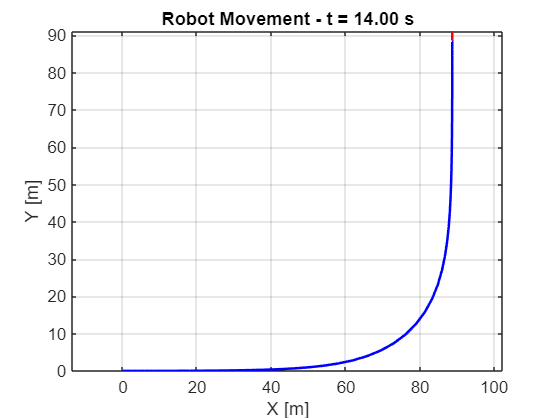

figure;
for i = 1:length(t)
    plot(pose(1,1:i), pose(2,1:i), 'b', 'LineWidth', 1.5); hold on; % Path traversed
    quiver(pose(1,i), pose(2,i), cos(theta_ref(i)), sin(theta_ref(i)), 2.5, 'r', 'LineWidth', 1.5);
    axis equal;
    grid on;
    xlabel('X [m]');
    ylabel('Y [m]');
    %xlim([0,50]);
    %ylim([0,45])
    title(sprintf('Robot Movement - t = %.2f s', t(i)));
    drawnow;
    hold off;
end

## MPC Test

% Control Signal
n = 2;
n_u = 2;

% Control Horizon
N = 10;

u = zeros(n_u, length(t) - N);
x_history = zeros(n, length(t) - N +1);

% Control Matrices
Q = 5*eye(2);
R = eye(2);
P = 10*eye(2);
Y = 3*eye(2);

% Robot Parameters
d = 0.5;    % Distance between Wheels [m]
r = 0.25;   % Wheel Radius [m]
robot_params = [d, l, r];

% Initial Pose
xk = [x0 y0]';
x_history(:,1) = xk;

for i = 1:length(u)
    if i == 1
        k = 1;
    else
        k = find(min(poseRef-xk),1)
    end
    % First we take the useful parameters of the trajectory
    poseRef = pose(:, i:i+N);
    thetaRef = theta_ref(1, i:i+N);
    % Computing the control signals
    u(:,i) = FHOCP(xk, Q, R, P, Y, N, n, n_u, delta_t, poseRef, thetaRef, robot_params);
    % Updating the State
    [xk, yk] = model_Robot_pointP(xk, u(:,i), delta_t);
    % States
    x_history(:,i+1) = xk;
end

------------------------------------
 La Pose Actual 
     0
     0

 Señal de Control 
   25.0000
    0.0000



k = 1

------------------------------------
 La Pose Actual 
    5.0000
    0.0000

 Señal de Control 
   25.0000
   -0.0000



k = 1

------------------------------------
 La Pose Actual 
   10.0000
   -0.0000

 Señal de Control 
   25.0000
    0.0000



k = 1

------------------------------------
 La Pose Actual 
   15.0000
    0.0000

 Señal de Control 
   25.0000
   -0.0000



k = 1

------------------------------------
 La Pose Actual 
   20.0000
    0.0000

 Señal de Control 
   25.0000
    0.0000



k = 1

------------------------------------
 La Pose Actual 
   25.0000
    0.0000

 Señal de Control 
   25.0000
    0.0217



k = 1

------------------------------------
 La Pose Actual 
   30.0000
    0.0043

 Señal de Control 
   25.0000
    0.0316



k = 1

------------------------------------
 La Pose Actual 
   35.0000
    0.0107

 Señal de Control 
   25.0000
    0.0459



k = 1

------------------------------------
 La Pose Actual 
   40.0000
    0.0198

 Señal de Control 
   24.9999
    0.0668



k = 1

------------------------------------
 La Pose Actual 
   45.0000
    0.0332

 Señal de Control 
   24.9998
    0.0971



k = 1

------------------------------------
 La Pose Actual 
   49.9999
    0.0526

 Señal de Control 
   24.9996
    0.1411



k = 1

------------------------------------
 La Pose Actual 
   54.9999
    0.0808

 Señal de Control 
   24.9992
    0.2050



k = 1

------------------------------------
 La Pose Actual 
   59.9997
    0.1218

 Señal de Control 
   24.9982
    0.2976



k = 1

------------------------------------
 La Pose Actual 
   64.9993
    0.1814

 Señal de Control 
   24.9963
    0.4314



k = 1

------------------------------------
 La Pose Actual 
   69.9986
    0.2676

 Señal de Control 
   24.9922
    0.6246



k = 1

------------------------------------
 La Pose Actual 
   74.9970
    0.3926

 Señal de Control 
   24.9837
    0.9021



k = 1

------------------------------------
 La Pose Actual 
   79.9938
    0.5730

 Señal de Control 
   24.9662
    1.2987



k = 1

------------------------------------
 La Pose Actual 
   84.9870
    0.8327

 Señal de Control 
   24.9307
    1.8607



k = 1

------------------------------------
 La Pose Actual 
   89.9731
    1.2049

 Señal de Control 
   24.8594
    2.6476



k = 1

------------------------------------
 La Pose Actual 
   94.9450
    1.7344

 Señal de Control 
   24.7201
    3.7304



k = 1

------------------------------------
 La Pose Actual 
   99.8891
    2.4804

 Señal de Control 
   24.4567
    5.1836



k = 1

------------------------------------
 La Pose Actual 
  104.7804
    3.5172

 Señal de Control 
   23.9806
    7.0662



k = 1

------------------------------------
 La Pose Actual 
  109.5765
    4.9304

 Señal de Control 
   23.1702
    9.3885



k = 1

------------------------------------
 La Pose Actual 
  114.2105
    6.8081

 Señal de Control 
   21.8921
   12.0721



k = 1

------------------------------------
 La Pose Actual 
  118.5890
    9.2225

 Señal de Control 
   20.0548
   14.9266



k = 1

------------------------------------
 La Pose Actual 
  122.5999
   12.2079

 Señal de Control 
   17.6777
   17.6777



k = 1

------------------------------------
 La Pose Actual 
  126.1355
   15.7434

 Señal de Control 
   14.9266
   20.0548



k = 1

------------------------------------
 La Pose Actual 
  129.1208
   19.7543

 Señal de Control 
   12.0721
   21.8921



k = 1

------------------------------------
 La Pose Actual 
  131.5352
   24.1328

 Señal de Control 
    9.3885
   23.1702



k = 1

------------------------------------
 La Pose Actual 
  133.4129
   28.7668

 Señal de Control 
    7.0662
   23.9806



k = 1

------------------------------------
 La Pose Actual 
  134.8261
   33.5629

 Señal de Control 
    5.1836
   24.4567



k = 1

------------------------------------
 La Pose Actual 
  135.8629
   38.4543

 Señal de Control 
    3.7304
   24.7201



k = 1

------------------------------------
 La Pose Actual 
  136.6089
   43.3983

 Señal de Control 
    2.6476
   24.8594



k = 1

------------------------------------
 La Pose Actual 
  137.1385
   48.3702

 Señal de Control 
    1.8607
   24.9307



k = 1

------------------------------------
 La Pose Actual 
  137.5106
   53.3563

 Señal de Control 
    1.2987
   24.9662



k = 1

------------------------------------
 La Pose Actual 
  137.7703
   58.3495

 Señal de Control 
    0.9021
   24.9837



k = 1

------------------------------------
 La Pose Actual 
  137.9508
   63.3463

 Señal de Control 
    0.6246
   24.9922



k = 1

------------------------------------
 La Pose Actual 
  138.0757
   68.3447

 Señal de Control 
    0.4314
   24.9963



k = 1

------------------------------------
 La Pose Actual 
  138.1620
   73.3440

 Señal de Control 
    0.2976
   24.9982



k = 1

------------------------------------
 La Pose Actual 
  138.2215
   78.3436

 Señal de Control 
    0.2050
   24.9992



k = 1

------------------------------------
 La Pose Actual 
  138.2625
   83.3435

 Señal de Control 
    0.1411
   24.9996



k = 1

------------------------------------
 La Pose Actual 
  138.2907
   88.3434

 Señal de Control 
    0.0971
   24.9998



k = 1

------------------------------------
 La Pose Actual 
  138.3101
   93.3433

 Señal de Control 
    0.0668
   24.9999



k = 1

------------------------------------
 La Pose Actual 
  138.3235
   98.3433

 Señal de Control 
    0.0459
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3327
  103.3433

 Señal de Control 
    0.0316
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3390
  108.3433

 Señal de Control 
    0.0217
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  113.3433

 Señal de Control 
   -0.0000
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  118.3433

 Señal de Control 
    0.0000
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  123.3433

 Señal de Control 
         0
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  128.3433

 Señal de Control 
    0.0000
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  133.3433

 Señal de Control 
   -0.0000
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  138.3433

 Señal de Control 
   -0.0000
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  143.3433

 Señal de Control 
         0
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  148.3433

 Señal de Control 
         0
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  153.3433

 Señal de Control 
         0
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  158.3433

 Señal de Control 
         0
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  163.3433

 Señal de Control 
         0
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  168.3433

 Señal de Control 
         0
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  173.3433

 Señal de Control 
         0
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  178.3433

 Señal de Control 
         0
   25.0000



k = 1

------------------------------------
 La Pose Actual 
  138.3433
  183.3433

 Señal de Control 
         0
   25.0000




figure()
plot(pose(1,:), pose(2,:), 'LineWidth', 1.5);
hold on;
plot(x_history(1,:), x_history(2,:), 'LineWidth', 1.5);
grid on;
xlabel('x [m]');
ylabel('y [m]');
title('Robot Pose');
legend('Reference', 'Path', Location='northwest')

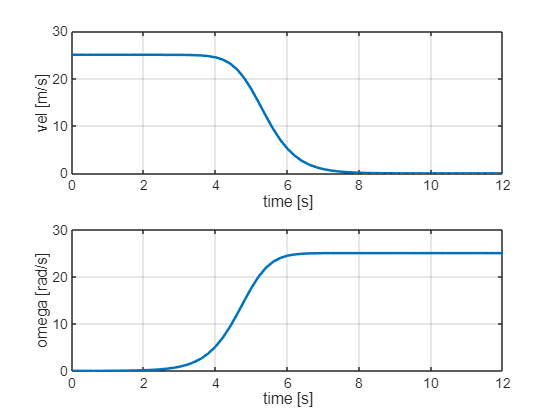


figure()
subplot(2,1,1)
plot(t(1,1:length(u)), u(1,:), 'LineWidth', 1.5);
grid on;
xlabel('time [s]');
ylabel('vel [m/s]');
subplot(2,1,2)
plot(t(1,1:length(u)), u(2,:), 'LineWidth', 1.5);
grid on;
xlabel('time [s]');
ylabel('omega [rad/s]');



pose_time = [t', pose'];
theta_time = [t', theta_ref'];


function x = ramp(t)
    x = t.*(t>=0);
end